# PROYECTO PRIME

## Modelado de la simulación de la transmisión de tramas de carga según el estándar de PRIME,  ITU-T G.9904

Teresa González García y María José Medina Hernández

format compact; clear all; close all;

## Implementación de todos los modos de comunicación de PRIME en el caso de canal sin distorsión y sin FEC 

### 1. Elección de los parámetros de simulación

#### Parámetros generales

Fs=250*10^3; % Frecuencia de muestreo
Ts=1/Fs; % Periodo de muestreo

#### Parámetros de modulación PSK

m_ary=[2 4 8]; % Número de símbolos de la constelación PSK
m_dpsk=log2(m_ary);

#### Parámetros de modulación OFDM

Estos parámetros han sido sacados del estándar, centrándonos únicamente en el payload.

Nc= 96; % Número de portadoras
NFFT=512; % Tamaño FFT
Ncp=48; % Tamaño prefijo ciclico
Tsimb=2.24*10^-3; % NFFT*Ts + Ncp*Ts. Duracion total simbolo OFDM
delta_f=Fs/NFFT; % Separacion entre f portadoras

#### Parámetros de corrección de errores

R=1/2; %Convolutional coding rate

#### Parámetros de aleatorización y desfase

% Secuencia PRBS
scrambler = [0,0,0,0,1,1,1,0,1,1,1,1,0,0,1,0,1,1,0,0,1,0,0,1,0,0,0,0,0,0,1,0,0,0,1,0,0,1,1,0,0,0,1,0,1,1,1,0,1,0,1,1,0,1,1,0,0,0,0,0,1,1,0,0,1,1,0,1,0,1,0,0,1,1,1,0,0,1,1,1,1,0,1,1,0,1,0,0,0,0,1,0,1,0,1,0,1,1,1,1,1,0,1,0,0,1,0,1,0,0,0,1,1,0,1,1,1,0,0,0,1,1,1,1,1,1,1];

#### Parámetros de simulación

Para calcular el número de símbolos OFDM por trama, tenemos en cuenta que, como máximo, esta puede durar 100ms ya que es el tiempo máximo en el que se puede considerar el canal estable cuando sea dispersivo. Obtenemos Nofdm = 44.

Tmax=100*10^-3; % Duración máxima de una trama
Nofdm= floor(Tmax/(Tsimb)); % Nofdm

Puesto que se quieren obtener valores de BER fiables inferiores incluso a 10^-4, se necesitan transmitir al menos 10^-4 bits si se quiere obtener esta sensibilidad. Para sencillez del código, se utilizará un número de bits proporcional al número de portadoras, a log2(m-ary) y al número de símbolos OFDM por trama. El mínimo común múltiplo de estos cuatro parámetros es mayor a 10^-4, por lo que es un tamaño válido. En total obtenemos 25344.

Nbits = Nc*lcm(2,3)*Nofdm;

A continuación, obtenemos el número de bits por trama y el número de tramas para modulación. 

Para calcular el número de bits por trama en cada modulación, se multiplica el número de símbolos/trama* bits/símbolo (número de portadoras*log2(m_ary). Se obtienen 4224 para DBPSK, 8448 para  DQPSK y12672 para D8PSK.

Para calcular el número total de tramas, se divide el número total de bits entre los bits por trama. En total obtenemos 6 para DBPSK, 3 para DQPSK y 2 para DBPSK.

Nbits_trama_DPSK= Nofdm*Nc*m_dpsk;
N_tramas_DPSK=Nbits./Nbits_trama_DPSK;

### 2. Comportamiento del sistema en un canal ideal

#### Transmisión con aleatorización 

% TODO: poner un flag para que aleatorice o no para demostrar que funciona sin y con aleatorización

% Generación de una secuencia de bits aleatoria
txbits = randi(2,1,Nbits)-1;

% Transmisión con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
x_tx_DBPSK= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT);
x_tx_DQPSK= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT);
x_tx_D8PSK= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT);

% Recepción con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
rxbits_DBPSK=receptor(x_tx_DBPSK, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
rxbits_DQPSK=receptor(x_tx_DQPSK, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
rxbits_D8PSK=receptor(x_tx_D8PSK, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);

#### Cálculo del error de transmisión

Cálculo del error de transmisión mediante la comparación de los bits transmitidos con los recibidos

error_dbpsk = sum(abs(txbits-rxbits_DBPSK))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-rxbits_DQPSK))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-rxbits_D8PSK))

error_d8psk = 0

Como se puede observar, el error de transmisión-recepción, incluyendo aleatorización es 0. Esto es lo esperable, ya que se está simulando el sistema en un canal ideal (h[n]=1) y sin ruido.

#### Transmisión en presencia de ruido AWGN

A continuación se van a comparar las gráficas de BER vs SNR teóricas y reales para cada tipo de modulación.

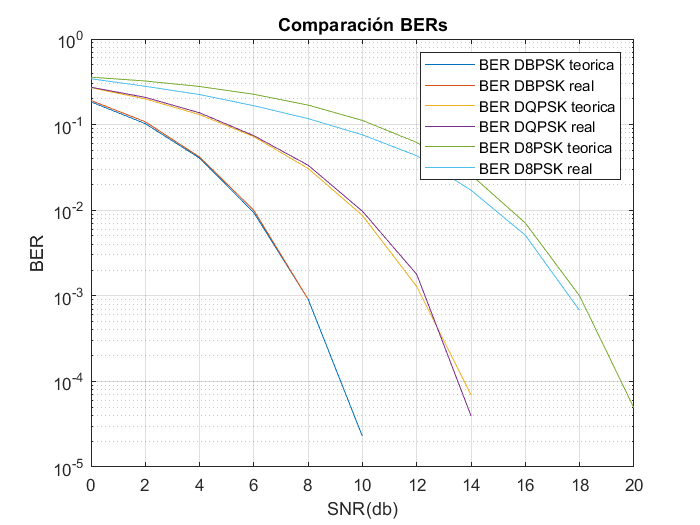

% vector SNR
SNR_db = 0:2:35;

% Cálculo del factor de ancho de banda para distribuir SNR tan solo en la parte
% del espectro con portadoras (Nc)
fb = 10*log10( (NFFT/2)/Nc);

%BER's teoricas de cada modulacion
BER_teor_DBPSK= DBPSK_BER(SNR_db);
BER_teor_DBPSK(find(BER_teor_DBPSK<1e-6))=NaN;
BER_teor_DQPSK= DQPSK_BER(SNR_db);
BER_teor_DQPSK(find(BER_teor_DQPSK<1e-6))=NaN;
BER_teor_D8PSK= D8PSK_BER(SNR_db);
BER_teor_D8PSK(find(BER_teor_D8PSK<1e-6))=NaN;

% Bucle calculo BER_real_DBPSK
for k=1:length(SNR_db)
    
    % Se añade AWGN a la señal de entrada, ajustando la SNR con el factor de ancho de banda.
    y_noise_dbpsk=awgn(x_tx_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_dqpsk=awgn(x_tx_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_d8psk=awgn(x_tx_D8PSK,SNR_db(k)-fb,'measured');
    
    % Se calcula la salida del receptor en presencia de AWGN para cada
    % modulación.
    y_rx_noise_dbpsk=receptor(y_noise_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_dqpsk=receptor(y_noise_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_d8psk=receptor(y_noise_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    % Se calcula la diferencia entre los bits de información transmitidos y
    % los bits a la salida del receptor.
    diferencia_dbpsk=abs(txbits-y_rx_noise_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_d8psk);
    
    % Se calcula las BERs reales como el número total de bits diferentes
    % entre el número de bits transmitidos.
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

% Representacion BER vs SNR para todos los tipos de modulacion
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

Como se esperaba, la BER real es ligeramente mayor que la teórica en todos los casos. Esta mínima diferencia se debe a la presencia de AWGN, pero se hará mayor cuando se incluya un canal no ideal. 

Para una SNR=5db, se puede ver que la BER real es prácticamente idéntica a la teórica en los casos tanto de DBPSK como DQPSK. Sin embargo, en el caso de D8PSK la diferencia es de 0.2.

Para una BER de $10^{-3}$, se necesita la siguiente SNR:

- DBPSK -> SNR= 8 db

- DQPSK -> SNR= 12 db

- D8PSK -> SNR= 18 db

Por tanto se demuestra que a mayor número de puntos de la constelación (en este caso D8PSK), se necesita una mayor SNR para obtener el mismo nivel de BER, y también la BER real difiere más que la teórica, ya que dichos puntos se encuentran más juntos.

## Inclusión de modelo de canal e inclusión de ecualizador

Se includen al modelo de simulación los efectos de un canal dispersivo h[n]. La expresión de este canal representa la atenuación que sufre la señal y los efectos de la suma de las réplicas de la señal debidas a los efectos del multicamino.

#### Expresión algebraica de la señal

Siendo s(t) la señal transmitida, y(t) la señal recibida y h(t) la respuesta al impulso del canal, la expresitón de y(t) en en función del efecto de la dispersión del canal queda:


$$y[n] = s[n] *h[n]$$


Puesto que el canal muestra la siguiente respuesta al impulso


$$h[n] = [ -0.1 , 0.3 , -0.5 , 0.7 , -0.9 , 0.7 , -0.5 , 0.3 , -0.1 ]$$


La señal recibida queda:


$$y[n] = x[n]*h[n] = -0.1\cdot x[n]+0.3\cdot x[n-1]-0.5\cdot x[n-2]+0.5\cdot x[n-3]-0.9\cdot x[n-4]+0.7\cdot x[n-5]-0.5\cdot x[n-6]+0.3\cdot x[n-7]-0.1\cdot x[n-8]$$


#### Representación del canal

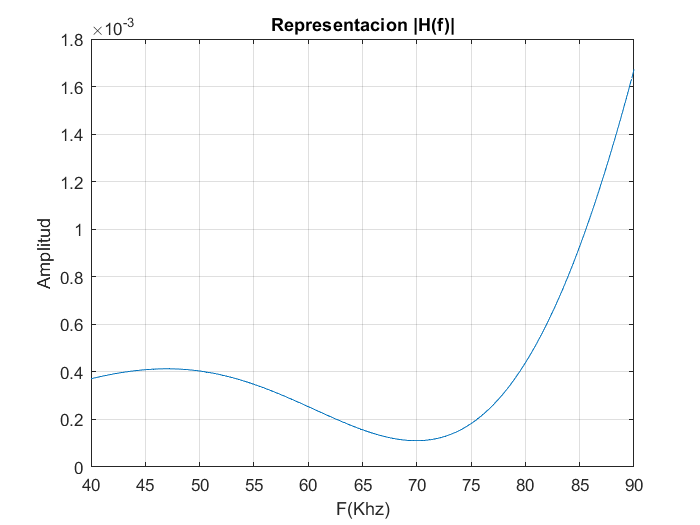

% Respuesta al impulso del canal
h=[-0.1,0.3,-0.5,0.7,-0.9,0.7, -0.5, 0.3, -0.1];
H=fft(h,NFFT)/NFFT; % Espectro de la respuesta al impulso
f=linspace(-Fs/2,Fs/2, length(H)); % Vector de frecuencias

%Representacion |H(f)| en el dominio de la frecuencia (unidades naturales)
figure
plot(f/1000,abs(fftshift(H)));
title('Representacion |H(f)|');
xlabel('F(Khz)');
xlim([40,90]);
ylabel('Amplitud');
grid on

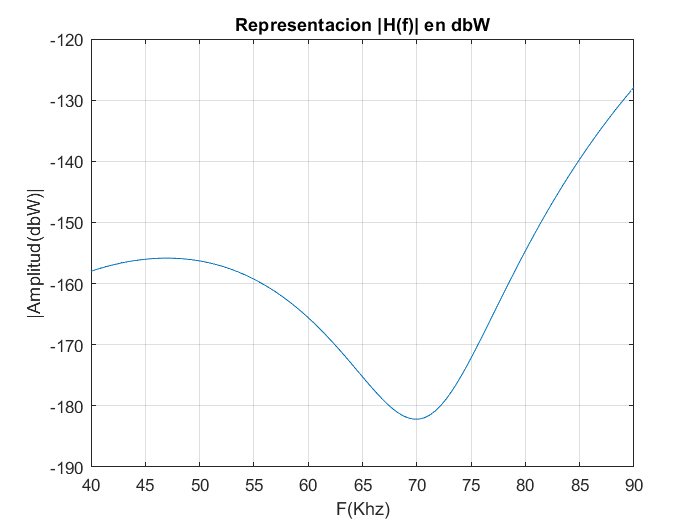

% Representacion |H(f)| el dominio de la frecuencia (db)
figure
plot (f/1000,20*log(abs(fftshift(H))))
title('Representacion |H(f)| en dbW');
xlabel('F(Khz)');
ylabel('|Amplitud(dbW)|');
grid on
xlim([40,90]);

xlim([40 90])
ylim('auto')

Como se puede observar en las gráficas del espectro del canal, en la banda de paso, las frecuencias en torno a 70 kHz son las que se ven más atenuadas (-182 dbW). Por el contrario, para las frecuencias más cercanas al límite superior de 80kHz, la atenuación es mucho menor (-129 dbW).

#### Efecto del canal en la transmisión

Se incluye el efecto del canal en la transmisión sin añadir prefijo cíclico ni ecualización en recepción.

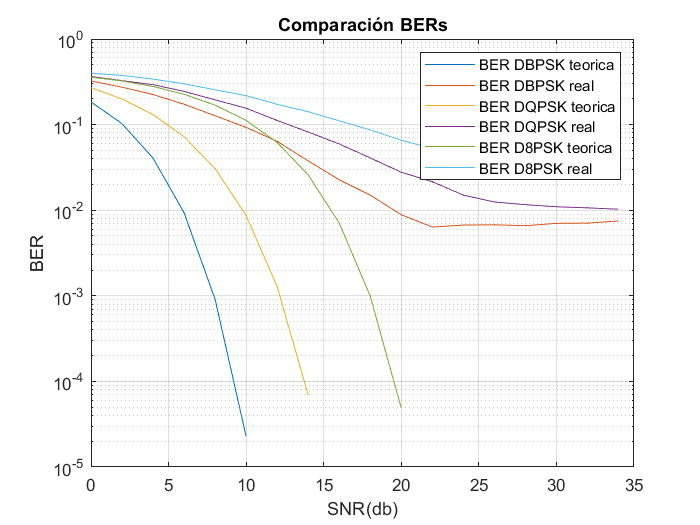

% Convolucion lineal  de la señal transmitida
y_canal_DBPSK=conv(x_tx_DBPSK,h);
y_canal_DBPSK =y_canal_DBPSK(1:end-length(h)+1);
y_canal_DQPSK=conv(x_tx_DQPSK,h);
y_canal_DQPSK =y_canal_DQPSK(1:end-length(h)+1);

y_canal_D8PSK=conv(x_tx_D8PSK,h);
y_canal_D8PSK =y_canal_D8PSK(1:end-length(h)+1);
% AWGN
for k=1:length(SNR_db)
    %y_noise=zeros(1, length(x_tx_DBPSK));
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_dqpsk=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_d8psk=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

De nuevo, la transmisión DBPSK es la que presenta menor BER debido a que es en la que los distintos puntos de la constelación se encuentran más separados. Sin embargo, esta BER no decrece siempre con el aumento de la SNR, sino que se estanca a partir de los 25 dB. El motivo es que la transmisión en un canal dispersivo sin utilizar prefijo cíclico ni ecualización presenta un fondo de ruido en recepción del orden de 0.007 en el mejor de los casos (DBPSK) debido a la interferencia intersimbólica.  Para DQPSK, este fondo de ruido es de 0.009 y para D8PSK, de 0.2 para una SNR de 30 dB. 

#### Transmisión con prefijo cíclico y ecualización

A continuación se realiza una transmisión incluyendo un prefijo cíclico, de manera que más tarde en el proceso de ecualización sea posible contrarrestar los efectos del canal. La razón por la que es necesario incluir este prefijo cíclico es que en el dominio discreto


$$Y(k) \neq X(k) \cdot H(k)$$


Sin embargo, sí que se cumple


$$Yc(k) =  X(k) \cdot H(k) $$


Siendo Yc la transformada de Fourier de la convolución circular de x[n] con h[n]. 

Puesto que el canal se modela como una convolución lineal, para que sea equivalente a la convolución circular es necesario añadir a la señal transmitida un prefijo cíclico igual a las últimas mustras de esta señal. Tras realizar esta operación, si que es posible ecualizar la señal al conocer el canal, ya que


$$H(k) = \frac{Yc(k)}{X(k)}$$


% Transmisión con prefijo cíclico
x_tx_DBPSK_cp= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_DQPSK_cp= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_D8PSK_cp= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT, Ncp);

% Efecto del canal
y_canal_DBPSK_cp=conv(x_tx_DBPSK_cp,h);
y_canal_DBPSK_cp =y_canal_DBPSK_cp(1:end-length(h)+1);

y_canal_DQPSK_cp=conv(x_tx_DQPSK_cp,h);
y_canal_DQPSK_cp =y_canal_DQPSK_cp(1:end-length(h)+1);

y_canal_D8PSK_cp=conv(x_tx_D8PSK_cp,h);
y_canal_D8PSK_cp =y_canal_D8PSK_cp(1:end-length(h)+1);

Suponemos que desconocemos el canal pero que sí conocemos el primer simbolo OFDM de cada trama, el cual actúa de piloto para poder obtener la expresión del canal. Esto se realiza mediante la división de la señal piloto recibida entre la conocida.

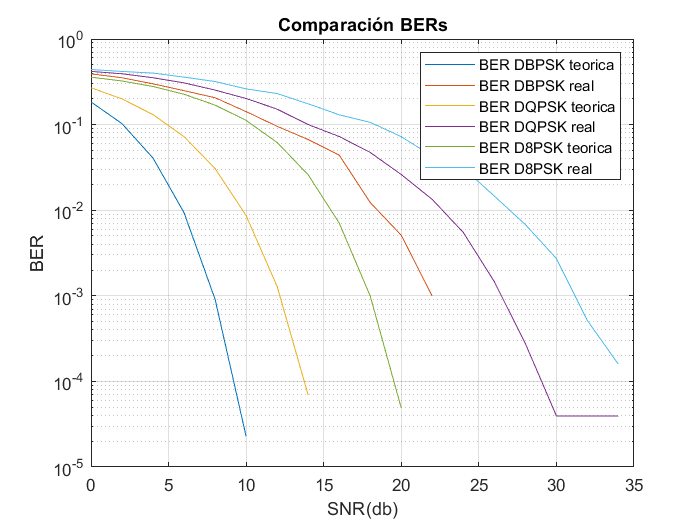


% AWGN
for k=1:length(SNR_db)
  
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK_cp,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk_cp=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_dqpsk_cp=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_d8psk_cp=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk_cp);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk_cp);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk_cp);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

Como se puede observar en la figura, el fondo de ruido del orden de $10^{-2}$ que encontrábamos en el apartado anterior causado por la interferncia intersimbólica (ISI) ha desaparecido completamente al ecualizar. Sin embargo, la BER teórica es significativamente menor a la real. Puesto que el canal ha sido estimado en presencia de AWGN, este no es exacto, con lo que es natural que exista una diferencia entre el error teórico y el obtenido. Para obtener una SNR de $10^{-3}$, teóricamente para DBPSK se necesita una SNR de 8 dB y 12 dB en la práctica, lo que resulta en una diferencia de 4 dB. Para DQPSK, son 18 dB en la teoría y 21 dB en la simulada (3 dB de diferencia). Por último, en D8PSK son 27 dB en teoría y 31 en la práctica, con una diferencia de nuevo de 4 dB.

## Implementación de todos los modos de comunicación de PRIME con FEC 

A continuación se va a realizar una transmisión utilizando un código de corrección de errores convolucional. El código definido por el estándar ITU-T G.9904  tiene un ratio R = 1/2, por lo que el codificador produce dos bits de salida por cada bit de entrada. Además, se añaden 8 bits de flushing, los cuales sirven para resetear los registros del codificador al final de cada trama, de manera que los primeros bits de cada trama no se vean afectados por los últimos de la anterior. 

Además del FEC, se añade un módulo de inerleaving, el cual sirve para cambiar las posiciones de los bits, de manera que si en el caso de producirse un pico de ruido, este no afecte a varios bits que se encuentren seguidos. La razón detrás de esta implementación es que los códigos de corrección de errores pueden corregir fallos hasta cierto umbral de número de bits erróneos. Si se supera este umbral, es posible que la señal original no se pueda recuperar. Por lo tanto, y en particular teniendo que los códigos convolucionales poseen memoria, distribuyéndose el ruido entre los bits adyacentes, es mejor dispersar los errores a lo largo de la señal en lugar de encontralos seguidos.

### 4. Modificación de los parámetros de simulación

Debido a la redundancia introducida por el codificador y a los bits de flushing, es necesario reducir los bits de información que caben en cada trama de la siguiente manera


$$Nbits_{TRAMA, INFO} = \frac{Nbits_{TRAMA}-Nbits_{FLUSH}}{2}$$


Puesto que el número de bits de información queda reducido a aproximadamente la mitad, para cumplir con el requisito de valores de BER fiables del orden de $10^{-4}$, es necesario duplicar el número de tramas enviadas.

Ntramas = 2*N_tramas_DPSK; % Doblamos el número de tramas
Nflush=8;

% Cálculo del nuevo número de bits de información por trama
Nbits_trama_DPSK_info(1) = Ntramas(1)*((Nbits_trama_DPSK(1)-Nflush)*R);
Nbits_trama_DPSK_info(2) = Ntramas(2)*((Nbits_trama_DPSK(2)-Nflush)*R);
Nbits_trama_DPSK_info(3) = Ntramas(3)*((Nbits_trama_DPSK(3)-Nflush)*R);

% Cálculo del número de bits totales para cada modulación
txbits_DBPSK = randi(2,1,Nbits_trama_DPSK_info(1))-1;
txbits_DQPSK = randi(2,1,Nbits_trama_DPSK_info(2))-1;
txbits_D8PSK = randi(2,1,Nbits_trama_DPSK_info(3))-1;


### 5. Simulación con FEC

A continuación se lleva a cabo la simulación de la transmisión incluyendo los módulos de correción de errores e interleaving.

% Transmisión con FEC e interleaving
x_tx_DBPSK_cp_FEC= transmisor(txbits_DBPSK', m_ary(1), Nbits_trama_DPSK(1), Ntramas(1), Nc,scrambler, Nofdm, NFFT, Ncp, R);
x_tx_DQPSK_cp_FEC= transmisor(txbits_DQPSK', m_ary(2), Nbits_trama_DPSK(2), Ntramas(2), Nc,scrambler, Nofdm, NFFT, Ncp, R);
x_tx_D8PSK_cp_FEC= transmisor(txbits_D8PSK', m_ary(3), Nbits_trama_DPSK(3), Ntramas(3), Nc,scrambler, Nofdm, NFFT, Ncp, R);

Cálculo de la BER para transmisión con FEC e interleaving

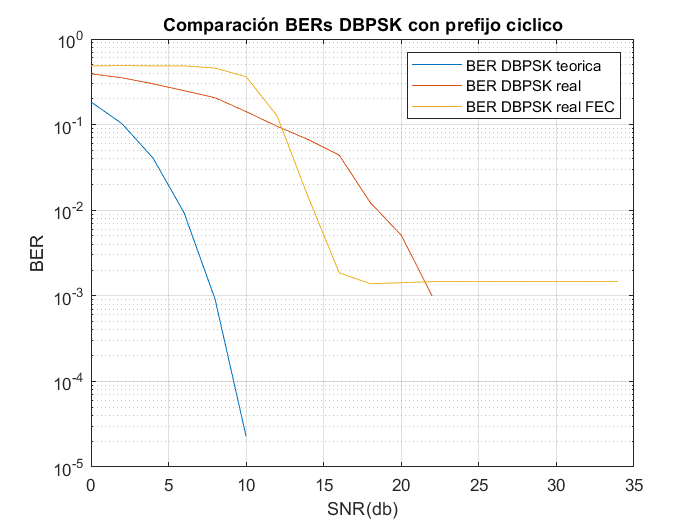

y_canal_DBPSK_cp_FEC=conv(x_tx_DBPSK_cp_FEC,h);
y_canal_DBPSK_cp_FEC =y_canal_DBPSK_cp_FEC(1:end-length(h)+1);

y_canal_DQPSK_cp_FEC=conv(x_tx_DQPSK_cp_FEC,h);
y_canal_DQPSK_cp_FEC =y_canal_DQPSK_cp_FEC(1:end-length(h)+1);

y_canal_D8PSK_cp_FEC=conv(x_tx_D8PSK_cp_FEC,h);
y_canal_D8PSK_cp_FEC =y_canal_D8PSK_cp_FEC(1:end-length(h)+1);
 
for k=1:length(SNR_db)
  
    y_noise_canal_dbpsk_FEC=awgn(y_canal_DBPSK_cp_FEC,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk_FEC=awgn(y_canal_DQPSK_cp_FEC,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk_FEC=awgn(y_canal_D8PSK_cp_FEC,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk_cp_FEC=receptor(y_noise_canal_dbpsk_FEC, m_ary(1), Nbits_trama_DPSK(1), Ntramas(1), Nc, scrambler, Nofdm, NFFT, Ncp, R);
    y_rx_noise_canal_dqpsk_cp_FEC=receptor(y_noise_canal_dqpsk_FEC, m_ary(2), Nbits_trama_DPSK(2), Ntramas(2), Nc, scrambler, Nofdm, NFFT, Ncp, R);
    y_rx_noise_canal_d8psk_cp_FEC=receptor(y_noise_canal_d8psk_FEC, m_ary(3), Nbits_trama_DPSK(3), Ntramas(3), Nc, scrambler, Nofdm, NFFT, Ncp, R);
    
 
    diferencia_dbpsk=abs(txbits_DBPSK-y_rx_noise_canal_dbpsk_cp_FEC);
    diferencia_dqpsk=abs(txbits_DQPSK-y_rx_noise_canal_dqpsk_cp_FEC);
    diferencia_d8psk=abs(txbits_D8PSK-y_rx_noise_canal_d8psk_cp_FEC);
    
    BER_real_DBPSK_FEC(k)= (sum(diferencia_dbpsk)/length(txbits_DBPSK));
    BER_real_DBPSK_FEC(find(BER_real_DBPSK_FEC<1e-6))=NaN;
    
    BER_real_DQPSK_FEC(k)= (sum(diferencia_dqpsk)/length(txbits_DQPSK));
    BER_real_DQPSK_FEC(find(BER_real_DQPSK_FEC<1e-6))=NaN;
    
    BER_real_D8PSK_FEC(k)= (sum(diferencia_d8psk)/length(txbits_D8PSK));
    BER_real_D8PSK_FEC(find(BER_real_D8PSK_FEC<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK_FEC)
title('Comparación BERs DBPSK con prefijo ciclico')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DBPSK real FEC')
grid on

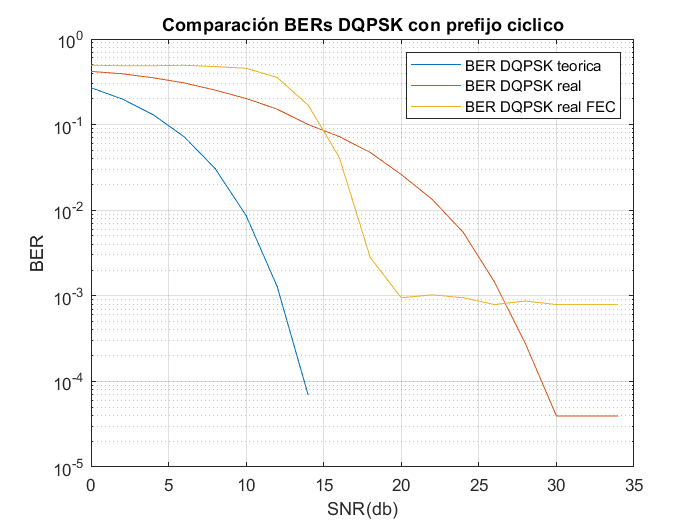



figure
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK_FEC)
title('Comparación BERs DQPSK con prefijo ciclico')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DQPSK teorica', 'BER DQPSK real', 'BER DQPSK real FEC')
grid on

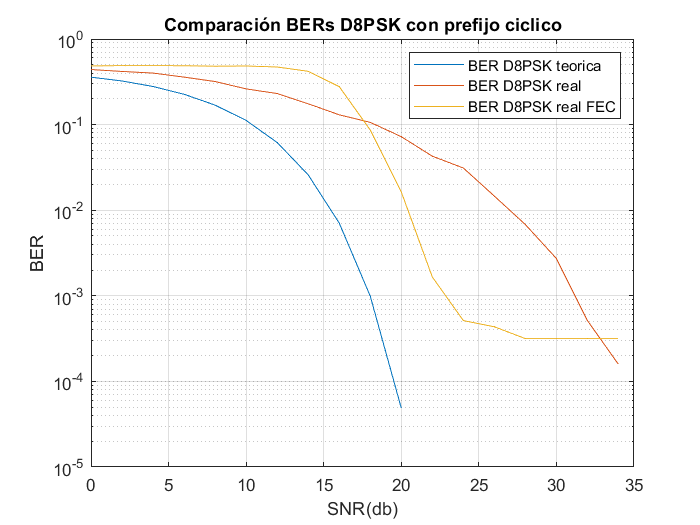


figure
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK_FEC)
title('Comparación BERs D8PSK con prefijo ciclico')
xlabel('SNR(db)')
ylabel('BER')
legend('BER D8PSK teorica', 'BER D8PSK real', 'BER D8PSK real FEC')
grid on

En las figuras anteriores se pueden comparar las BERs teóricas, reales y reales con módulos de FEC e interleaving para la transmisión en canal dispersivo en presencia de AWGN. Para SNRs altas, la BER real con FEC es mejor que sin FEC, aunque significativamente peor que la teórica para un canal AWGN. Es destacable el hecho de que para SNRs bajas, la BER es mayor si se utiliza código de corrección de errores. Esto se debe a que, como se ha explicado antes, los códigos de corrección de errores son capaces de recuperar la señal original hasta un umbral de número de bits erróneos. Además, debido a su naturaleza con memoria, un error en un bit influenciará a los que se encuentren próximos a este (por ello se introduce el módulo de interleaving, para poder dispersar el error). Por lo tanto, si la SNR es baja, el número de bits erróneos será alto y será imposible recuperar la señal original. 

En particular, para BPSK la BER se encuentra estancada en 0.4 hasta una SNR de 8 dB, para BQPSK hasta 10 dB y para D8PSK hasta 14 dB. 

Para obtener una BER de $10^{-3}$, para DBPSK se necesita una SNR de 8 dB de forma teórica, de 21 dB si se incluye un módulo de FEC y de 22 dB si no se incluye. Para DQPSK se necesitan 12 dB, 21 dB y 27 dB, respectivamente. Por último, para D8PSK se necesitan 18 dB, 28 dB y 32 dB, respectivamente. Por tanto, la diferencia entre el uso o no de FEC es de 1 dB en el caso de DBPSK, 6 dB para DQPSK y 4 dB para D8PSK, por lo que se compensa considerablemente el aumento de complejidad del transmisor y receptor. 

## Conclusión

A la vista de los resultados, en medios dispersivos como las líneas de potencia, si la SNR es lo suficientemente alta, es conveniente utilizar el módulo de corrección de errores del estándar del ITU-T G.9904, el cual es opcional, ya que disminuye considereablemente el error en recepción, en especial para DQPSK y D8PSK (6 dB y 4 dB, respectivamente). Sin embargo, para SNRs bajas, el FEC introduce un error que no se produce al símplemente al ecualizar, por lo que el uso de este módulo es desaconsejable. 